# TP Sae 22 :

4 mise en oeuvre de l'algo de Karplus-Strong

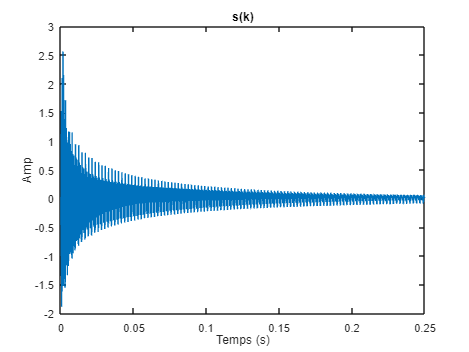

clear all; close all;

Fe = 44100;
F0 = 440;
a = 0.99;
d = .25;

L = round(Fe/F0);
N = round(d*Fe);

e = [randn(1,L), zeros(1,N-L)];
s = zeros(1,N);
x = zeros(1,N);
y = zeros(1,N);
DL = zeros(1,L);
for k=2:N
    x(k) = DL(L);
    y(k) = (a/2)*(x(k)+x(k-1));
    s(k) = e(k)+y(k);
    DL(2:L)=DL(1:L-1);
    DL(1) = s(k);
end
soundsc(s,Fe);


% Tracer le signal temporel avec les abscisse en seconde
t = (0:N-1) / Fe;  

figure;
plot(t, s);
xlabel('Temps (s)');
ylabel('Amp');
title('s(k)');

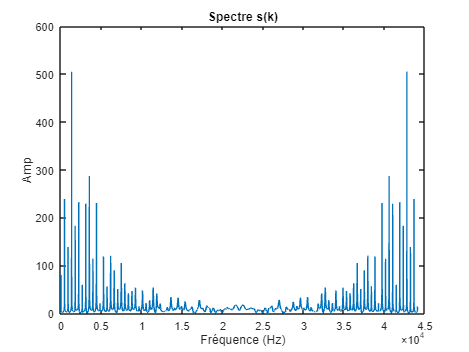


% Calculer et tracer le spectre du signal

f = (0:N-1)/N*Fe;

plot(f, abs(fft(s)));
xlabel('Fréquence (Hz)');
ylabel('Amp');
title('Spectre s(k)');

Jouer 2 notes à la suite

% Jouer note
F0_1 = 440;
L1 = round(Fe / F0_1);
N1 = round(d * Fe);

e1 = [randn(1, L1), zeros(1, N1 - L1)];
s1 = zeros(1, N1);
x1 = zeros(1, N1);
y1 = zeros(1, N1);
DL1 = zeros(1, L1);
for k = 2:N1
    x1(k) = DL1(L1);
    y1(k) = (a / 2) * (x1(k) + x1(k - 1));
    s1(k) = e1(k) + y1(k);
    DL1(2:L1) = DL1(1:L1 - 1);
    DL1(1) = s1(k);
end

% Deuxième note
F0_2 = 587;
L2 = round(Fe / F0_2);
N2 = round(d * Fe);

e2 = [randn(1, L2), zeros(1, N2 - L2)];
s2 = zeros(1, N2);
x2 = zeros(1, N2);
y2 = zeros(1, N2);
DL2 = zeros(1, L2);
for k = 2:N2
    x2(k) = DL2(L2);
    y2(k) = (a / 2) * (x2(k) + x2(k - 1));
    s2(k) = e2(k) + y2(k);
    DL2(2:L2) = DL2(1:L2 - 1);
    DL2(1) = s2(k);
end

s = [s1, s2];

soundsc(s, Fe);
